TCSPC simulation data generation

Generate decays and IRF (Gaussian) using random number generators of exponential and Gaussian distribution respectively. Then bin the data in histogram (380 bins, 0-20ns)

%background count rate
bg = 10; %counts per s
%IRF width
irf_sigma = 1e-5; %ns
%Acquisition time
run_time = 20*60; %s 
%photon count rate is 2500 counts per s
n_photon = (2500-bg)*run_time; %no. of photons detected
%lifetimes from 0.2ns to 2 ns (step = 0.2ns)
%can define different arrays of tau
tau = linspace(0.2,2,10);
y = ones(n_photon,1);
[Tau,Y] = meshgrid(tau,y);
t0 = 10/19; %offset ns
%total time
t_tot = normrnd(t0,irf_sigma,size(Tau)) + exprnd(Tau);
edges = 0:1/19:20;

%2D array to store Intensity curves (row) of different lifetimes (col)
histCounts = zeros(numel(edges)-1, size(t_tot, 2));

for col = 1:size(t_tot, 2)
    histCounts(:, col) = histcounts(t_tot(:, col), edges);
end
t = edges(1,1:end-1)'%time-axis

t =          0
    0.0526
    0.1053
    0.1579
    0.2105
    0.2632
    0.3158
    0.3684
    0.4211
    0.4737


plot(t,histCounts(:,2));
fit(edges(1,60:end-1)',histCounts(60:end,2),'exp1')

ans =      General model Exp1:
     ans(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   7.488e-07  (-0.01292, 0.01292)
       b =      0.5411  (-904, 905.1)

Export generated data

csvwrite('decay_data/mono_exp.csv',histCounts)

Deconvolution

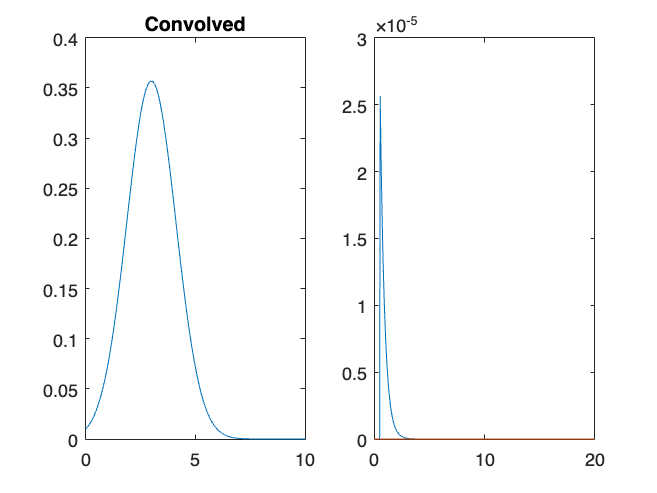

kernel = 3.6e5*normpdf(t, t0, irf_sigma);  % Gaussian kernel (IRF)
plot(t,abs(ifft(fft(histCounts(1:end,2))/fft(kernel))))

% Deconvolve the convolved data with Tikhonov regularization
% alpha = 0.01;  % Regularization parameter
% deconvolvedData = deconvreg(histCounts, kernel,alpha);
% plot(t,deconvolvedData);

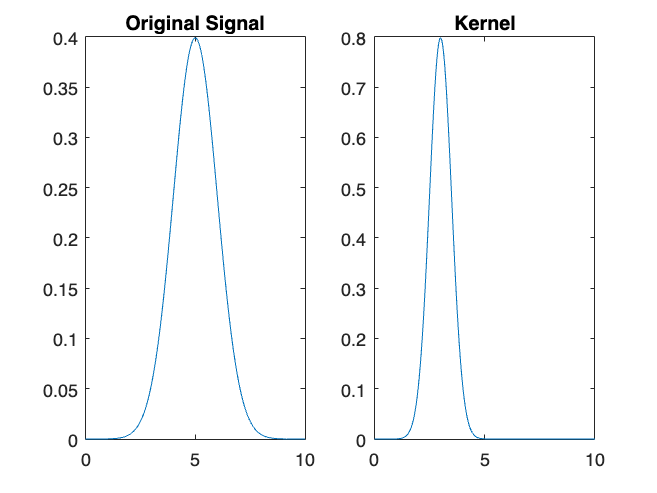

% Example data
x = 0:0.01:10;
originalSignal = normpdf(x, 5, 1);  % Original signal
kernel = normpdf(x, 3, 0.5);  % Gaussian kernel
resultSignal = conv(originalSignal,kernel,'same')/sum(kernel);

% Inverse Fourier transform to obtain the deconvolved signal
deconvolvedSignal = ifft(fft(resultSignal)/fft(kernel))*sum(kernel);

% Plot the original signal, kernel, and deconvolved signal
figure;
subplot(1, 2, 1);
plot(x, originalSignal);
title('Original Signal');

subplot(1, 2, 2);
plot(x, kernel);
title('Kernel');

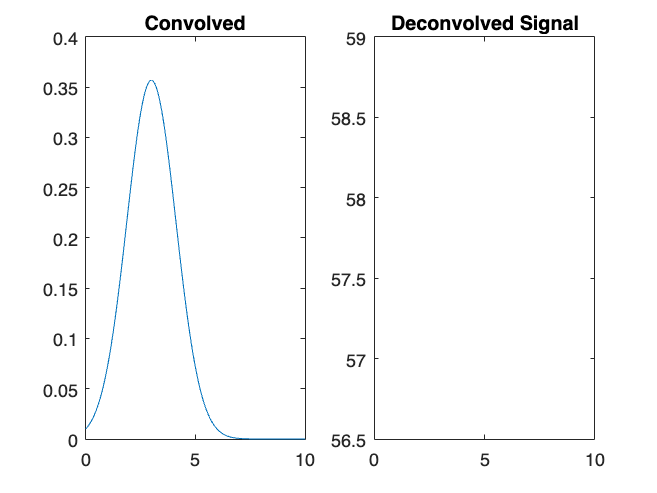


figure;
subplot(1, 2, 1);
plot(x, resultSignal);
title('Convolved');

subplot(1, 2, 2);
plot(x, real(deconvolvedSignal));
title('Deconvolved Signal');